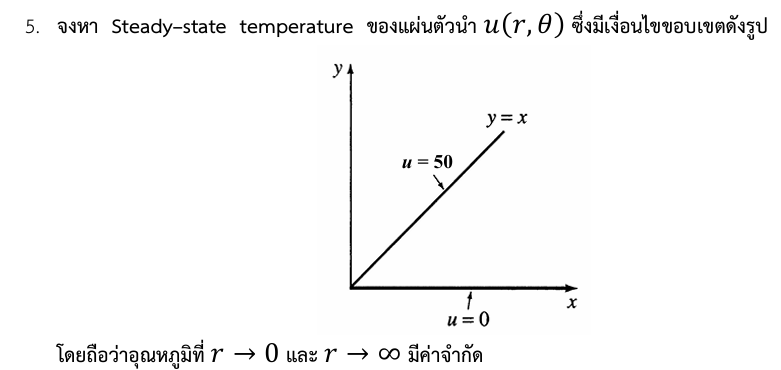

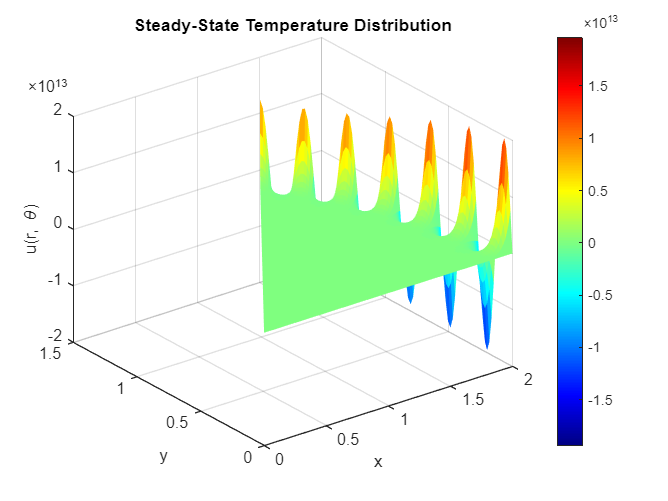

clc;
clear;
clearvars;
close all;
% Define parameters
N = 50; % Number of terms in the series
r = linspace(0, 2, 100); % Radial coordinate (0 to 2)
theta = linspace(0, pi/4, 100); % Angular coordinate (0 to pi/4)

% Create meshgrid for r and theta
[R, Theta] = meshgrid(r, theta);

% Initialize solution u
U = zeros(size(R));

% Solve using separation of variables
for n = 1:N
    % Coefficient (A_n)
    An = (2 / (n * pi)) * (1 - cos(n * pi / 4));
    % Add term to the solution
    U = U + An * sin(n * Theta) .* (R .^ n);
end

% Convert to Cartesian coordinates for visualization
X = R .* cos(Theta);
Y = R .* sin(Theta);

% Plot the solution
figure;
surf(X, Y, U, 'EdgeColor', 'none');
colormap(jet);
colorbar;
title('Steady-State Temperature Distribution');
xlabel('x');
ylabel('y');
zlabel('u(r, \theta)');
view(3);

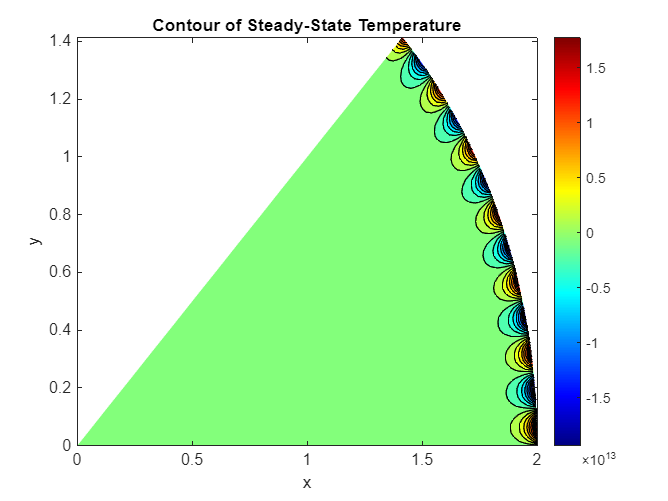


% Contour plot
figure;
contourf(X, Y, U, 20);
colormap(jet);
colorbar;
title('Contour of Steady-State Temperature');
xlabel('x');
ylabel('y');

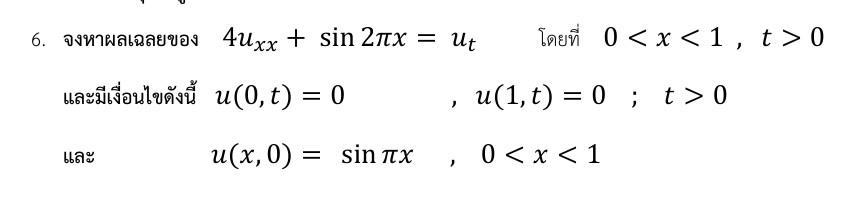

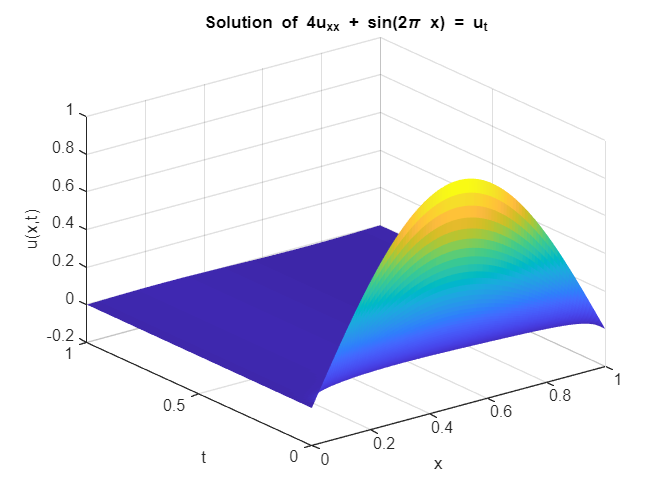

clear;clearvars;clf;
% Parameters
L = 1;            % Length of the spatial domain
Nx = 100;         % Number of spatial grid points
x = linspace(0, L, Nx)'; % Spatial grid
dx = x(2) - x(1); % Spatial step size

T = 1;            % Total simulation time
Nt = 500;         % Number of time steps
tspan = linspace(0, T, Nt); % Time grid

% Differential operator matrix for 4u_xx
e = ones(Nx, 1);
A = spdiags([e -2*e e], -1:1, Nx, Nx) / dx^2; 
A = 4 * A; % Coefficient of u_xx is 4
A(1, :) = 0; A(end, :) = 0; % Boundary conditions

% Initial condition
u0 = sin(pi * x);

% Solve using ODE solver
rhs = @(t, u) A * u + sin(2 * pi * x); % Define the right-hand side of the PDE
[~, U] = ode45(rhs, tspan, u0); % Solve the system of ODEs

% Plot the solution
[X, T] = meshgrid(x, tspan); % Create grids for plotting
U = reshape(U, Nt, Nx);

figure;
surf(X, T, U, 'EdgeColor', 'none');
xlabel('x'); ylabel('t'); zlabel('u(x,t)');
title('Solution of 4u_{xx} + sin(2\pi x) = u_t');